The infamous IBM Linear Congruential Random Number Generator

N=50000;
r=zeros(N,1);
coef = 65539;
bigint = 2^31;

seed = 1.;
r(1,1) = seed;

for i=2:N
    r(i,1)=mod(coef*r(i-1,1),bigint);
end

r=r/bigint;

Kth moment

Let's calculate 30 moments

Nmoments=30

Nmoments = 30

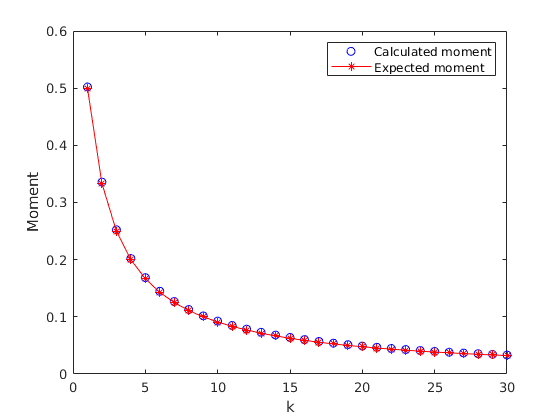

moment=zeros(Nmoments,1);
th_moment=zeros(Nmoments,1);

for i=1:Nmoments
    for k=1:N
        moment(i)=moment(i,1)+(r(k,1)^i);
    end
    th_moment(i,1)=1/(1+i);
end
moment=moment/N;
%th_moment=th_moment/N;



plot(1:Nmoments,moment,'bo');
xlabel('k');
ylabel('Moment');
hold on;
plot(1:Nmoments,th_moment,'r*-');
legend('Calculated moment','Expected moment');
hold off;

Looks like it passes the moments test.

Lets look at the auto-correlation test

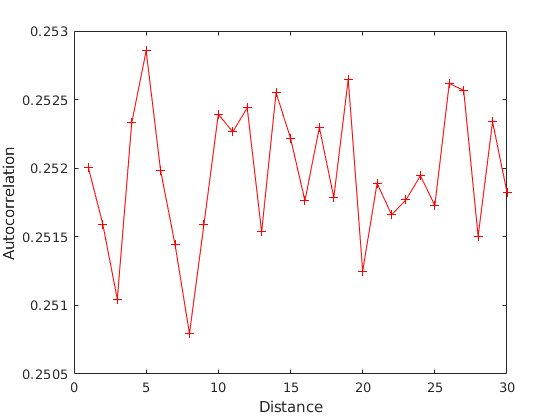

Dmax=30;
acor=zeros(Dmax,1);
for i=1:Dmax
    for k=1:N-Dmax
        acor(i,1)=acor(i,1)+r(k,1)*r(k+i,1);
    end
end
acor=acor/N;

plot(1:Dmax,acor,'r+-');
xlabel('Distance');
ylabel('Autocorrelation');